clc
clear

（1）获取暗通道图片

% 读取有雾图像
foggyImg = imread('./fog/fog2.jpg');
foggy_img1 = double(foggyImg);

% 获取暗通道图像
darkChannelImg = min(foggyImg, [], 3); % 取RGB三通道中最小值
filtered_img = imboxfilt(darkChannelImg ,3);

（2）获取A的估计值

% 估计A值
method = 2; 
% 1表示取有雾图最亮的点，2表示取暗通道图像最亮的地方所对应的有雾图的点
if method == 1
    % 方法1：取有雾图像中最亮的像素点
    [max_val, max_idx] = max(foggyImg(:));
    [max_row, max_col] = ind2sub(size(foggyImg), max_idx);
    A = foggyImg(max_row, max_col, :);
    A = double(max(A(:)));
elseif method == 2
    % 方法2：在暗通道图中选亮度前0.1%的点，再到对应像素坐标的有雾图找最亮的点作为A的估计值
    [M, N] = size(foggyImg);
    num_pixels = M * N;
    num_top_pixels = round(num_pixels * 0.001); % 选择前0.1%的像素
    J_dark_vec = reshape(filtered_img, [], 1);
    [~, indices] = sort(J_dark_vec, 'descend');
    top_indices = indices(1:num_top_pixels);
    A = double(max(foggyImg(top_indices)));
end

（3）估计t值

% 估计透射率t的值
w = 0.85; % 自定变量w，可以调整其值来影响去雾效果
darkChannelImg1 = double(darkChannelImg);
t = 1 - w*darkChannelImg1./A;

（4）公式求解

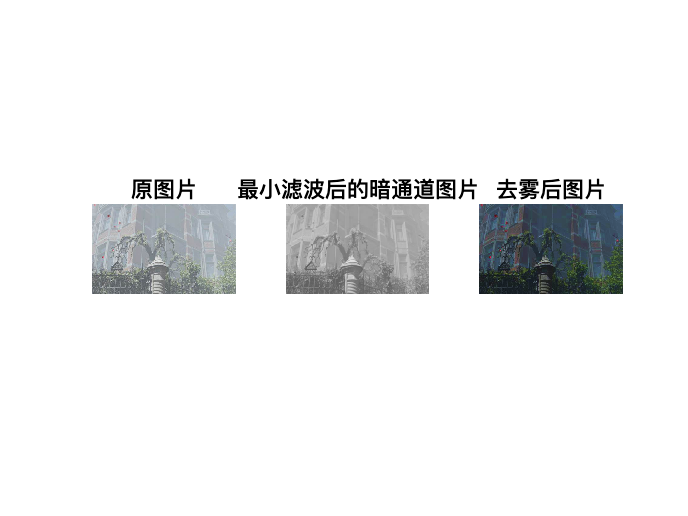

foggy_img2 = foggy_img1 - (1-t).*A;
foggy_img3 = foggy_img2./t;
J = double(foggy_img3);
J = uint8(J);
subplot(1, 3, 1), imshow(foggyImg);
title('原图片');
subplot(1, 3, 2), imshow(filtered_img);
title('最小滤波后的暗通道图片');
subplot(1, 3, 3), imshow(J);
title('去雾后图片')